WCZYTANIE DANYCH

clear; clc;
TRAIN = csvread('train.csv',1,0);
time = TRAIN(:,2);
AccX = TRAIN(:,3);
AccY = TRAIN(:,4);
AccZ = TRAIN(:,5);
GyroX = TRAIN(:,6);
GyroY = TRAIN(:,7);
GyroZ = TRAIN(:,8);
MagX = TRAIN(:,9);
MagY = TRAIN(:,10);
MagZ = TRAIN(:,11);
Temp = TRAIN(:,12);
Humi = TRAIN(:,13);
pitch = TRAIN(:,14);
roll = TRAIN(:,15);
yaw = TRAIN(:,16);

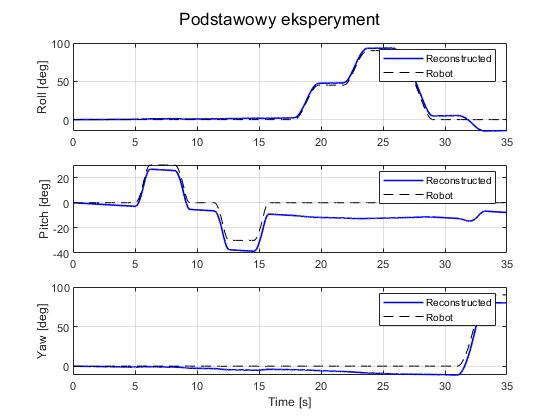

gyro = [GyroX GyroY GyroZ] * (pi/180/1000);
dt = [diff(time); median(diff(time))]; % sample intervals


q = [1;0;0;0];   % [qw qx qy qz]
N = length(time);

Q = zeros(N,4);
Euler = zeros(N,3);

for k = 1:N
    w = gyro(k,:)';   % angular velocity vector[rad/s]
    q = (eye(4) + 0.5*Omega(w)*dt(k)) * q;
    q = q / norm(q);
    
    Q(k,:) = q';
    Euler(k,:) = quat2eulerZYX(q); % [roll pitch yaw] in rad
end

%% Convert to degrees
Euler_deg = rad2deg(Euler);

figure;
subplot(3,1,1);
plot(time,Euler_deg(:,1),'b','LineWidth',1.2); hold on;
plot(time,roll,'k--'); ylabel('Roll [deg]');
legend('Reconstructed','Robot'); grid on;

subplot(3,1,2);
plot(time,Euler_deg(:,2),'b','LineWidth',1.2); hold on;
plot(time,pitch,'k--'); ylabel('Pitch [deg]');
legend('Reconstructed','Robot'); grid on;

subplot(3,1,3);
plot(time,Euler_deg(:,3),'b','LineWidth',1.2); hold on;
plot(time,yaw,'k--'); ylabel('Yaw [deg]'); xlabel('Time [s]');
legend('Reconstructed','Robot'); grid on;
sgtitle('Podstawowy eksperyment');


err_roll  = Euler_deg(:,1) - roll;
err_pitch = Euler_deg(:,2) - pitch;
err_yaw   = Euler_deg(:,3) - yaw;

% RMSE dla każdego kąta
rmse_roll  = sqrt(mean(err_roll.^2));
rmse_pitch = sqrt(mean(err_pitch.^2));
rmse_yaw   = sqrt(mean(err_yaw.^2));

% Wypisz wyniki w konsoli
fprintf('RMSE Roll  = %.3f deg\n', rmse_roll);

RMSE Roll  = 4.580 deg


fprintf('RMSE Pitch = %.3f deg\n', rmse_pitch);

RMSE Pitch = 9.123 deg


fprintf('RMSE Yaw   = %.3f deg\n', rmse_yaw);

RMSE Yaw   = 6.681 deg


Wplyw liniowego przyblizenia

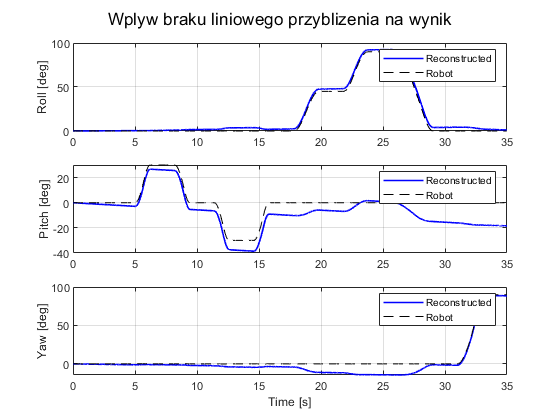

gyro = [GyroX GyroY GyroZ] * (pi/180/1000);

dt = [diff(time); median(diff(time))]; % sample intervals


q = [1;0;0;0];   % [qw qx qy qz]
N = length(time);

Q = zeros(N,4);
Euler = zeros(N,3);

for k = 1:N
    w = gyro(k,:)';   % wektor prędkości kątowej [rad/s]
    dt_k = dt(k);

    % Dokładna aktualizacja kwaternionu
    q = quatUpdateExact(q, w, dt_k);
    q = q / norm(q);

    Q(k,:) = q';
    Euler(k,:) = quat2eulerZYX(q); % [roll pitch yaw] w radianach
end

%% Convert to degrees
Euler_deg = rad2deg(Euler);

figure;
subplot(3,1,1);
plot(time,Euler_deg(:,1),'b','LineWidth',1.2); hold on;
plot(time,roll,'k--'); ylabel('Roll [deg]');
legend('Reconstructed','Robot'); grid on;

subplot(3,1,2);
plot(time,Euler_deg(:,2),'b','LineWidth',1.2); hold on;
plot(time,pitch,'k--'); ylabel('Pitch [deg]');
legend('Reconstructed','Robot'); grid on;

subplot(3,1,3);
plot(time,Euler_deg(:,3),'b','LineWidth',1.2); hold on;
plot(time,yaw,'k--'); ylabel('Yaw [deg]'); xlabel('Time [s]');
legend('Reconstructed','Robot'); grid on;
sgtitle('Wplyw braku liniowego przyblizenia na wynik');


err_roll  = Euler_deg(:,1) - roll;
err_pitch = Euler_deg(:,2) - pitch;
err_yaw   = Euler_deg(:,3) - yaw;

% RMSE dla każdego kąta
rmse_roll  = sqrt(mean(err_roll.^2));
rmse_pitch = sqrt(mean(err_pitch.^2));
rmse_yaw   = sqrt(mean(err_yaw.^2));

% Wypisz wyniki w konsoli
fprintf('RMSE Roll  = %.3f deg\n', rmse_roll);

RMSE Roll  = 2.596 deg


fprintf('RMSE Pitch = %.3f deg\n', rmse_pitch);

RMSE Pitch = 9.094 deg


fprintf('RMSE Yaw   = %.3f deg\n', rmse_yaw);

RMSE Yaw   = 6.929 deg


Wplyw kalibracji offsetu

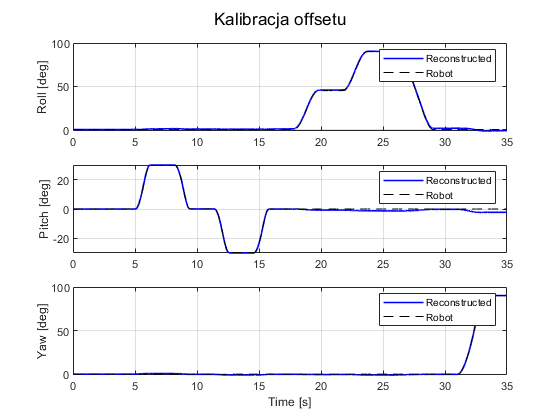

gyro = [GyroX GyroY GyroZ] * (pi/180/1000);
gyro = gyro - mean(gyro(100:700,:));
dt = [diff(time); median(diff(time))]; % sample intervals


q = [1;0;0;0];   % [qw qx qy qz]
N = length(time);

Q = zeros(N,4);
Euler = zeros(N,3);

for k = 1:N
    w = gyro(k,:)';   % angular velocity vector[rad/s]
    q = (eye(4) + 0.5*Omega(w)*dt(k)) * q;
    q = q / norm(q);
    
    Q(k,:) = q';
    Euler(k,:) = quat2eulerZYX(q); % [roll pitch yaw] in rad
end

%% Convert to degrees
Euler_deg = rad2deg(Euler);

figure;
subplot(3,1,1);
plot(time,Euler_deg(:,1),'b','LineWidth',1.2); hold on;
plot(time,roll,'k--'); ylabel('Roll [deg]');
legend('Reconstructed','Robot'); grid on;

subplot(3,1,2);
plot(time,Euler_deg(:,2),'b','LineWidth',1.2); hold on;
plot(time,pitch,'k--'); ylabel('Pitch [deg]');
legend('Reconstructed','Robot'); grid on;

subplot(3,1,3);
plot(time,Euler_deg(:,3),'b','LineWidth',1.2); hold on;
plot(time,yaw,'k--'); ylabel('Yaw [deg]'); xlabel('Time [s]');
legend('Reconstructed','Robot'); grid on;
sgtitle('Kalibracja offsetu');


err_roll  = Euler_deg(:,1) - roll;
err_pitch = Euler_deg(:,2) - pitch;
err_yaw   = Euler_deg(:,3) - yaw;

% RMSE dla każdego kąta
rmse_roll  = sqrt(mean(err_roll.^2));
rmse_pitch = sqrt(mean(err_pitch.^2));
rmse_yaw   = sqrt(mean(err_yaw.^2));

% Wypisz wyniki w konsoli
fprintf('RMSE Roll  = %.3f deg\n', rmse_roll);

RMSE Roll  = 0.780 deg


fprintf('RMSE Pitch = %.3f deg\n', rmse_pitch);

RMSE Pitch = 0.861 deg


fprintf('RMSE Yaw   = %.3f deg\n', rmse_yaw);

RMSE Yaw   = 0.503 deg


Bez aproksymacji liniowej z offsetem

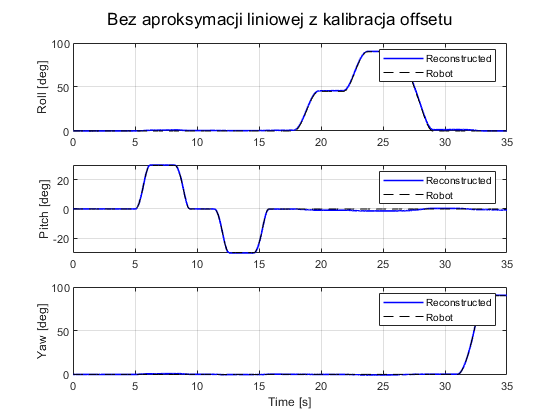

gyro = [GyroX GyroY GyroZ] * (pi/180/1000);
gyro = gyro - mean(gyro(100:700,:));
dt = [diff(time); median(diff(time))]; % sample intervals


q = [1;0;0;0];   % [qw qx qy qz]
N = length(time);

Q = zeros(N,4);
Euler = zeros(N,3);

for k = 1:N
    w = gyro(k,:)';   % wektor prędkości kątowej [rad/s]
    dt_k = dt(k);

    % Dokładna aktualizacja kwaternionu
    q = quatUpdateExact(q, w, dt_k);
    q = q / norm(q);

    Q(k,:) = q';
    Euler(k,:) = quat2eulerZYX(q); % [roll pitch yaw] w radianach
end

%% Convert to degrees
Euler_deg = rad2deg(Euler);

figure;
subplot(3,1,1);
plot(time,Euler_deg(:,1),'b','LineWidth',1.2); hold on;
plot(time,roll,'k--'); ylabel('Roll [deg]');
legend('Reconstructed','Robot'); grid on;

subplot(3,1,2);
plot(time,Euler_deg(:,2),'b','LineWidth',1.2); hold on;
plot(time,pitch,'k--'); ylabel('Pitch [deg]');
legend('Reconstructed','Robot'); grid on;

subplot(3,1,3);
plot(time,Euler_deg(:,3),'b','LineWidth',1.2); hold on;
plot(time,yaw,'k--'); ylabel('Yaw [deg]'); xlabel('Time [s]');
legend('Reconstructed','Robot'); grid on;
sgtitle('Bez aproksymacji liniowej z kalibracja offsetu');


err_roll  = Euler_deg(:,1) - roll;
err_pitch = Euler_deg(:,2) - pitch;
err_yaw   = Euler_deg(:,3) - yaw;

% RMSE dla każdego kąta
rmse_roll  = sqrt(mean(err_roll.^2));
rmse_pitch = sqrt(mean(err_pitch.^2));
rmse_yaw   = sqrt(mean(err_yaw.^2));

% Wypisz wyniki w konsoli
fprintf('RMSE Roll  = %.3f deg\n', rmse_roll);

RMSE Roll  = 0.781 deg


fprintf('RMSE Pitch = %.3f deg\n', rmse_pitch);

RMSE Pitch = 0.594 deg


fprintf('RMSE Yaw   = %.3f deg\n', rmse_yaw);

RMSE Yaw   = 0.347 deg


function Om = Omega(w)
    wx=w(1); wy=w(2); wz=w(3);
    Om = [ 0   -wx  -wy  -wz;
           wx   0    wz  -wy;
           wy  -wz   0    wx;
           wz   wy  -wx   0 ];
end

function eul = quat2eulerZYX(q)
    % Convert quaternion [qw qx qy qz] to Euler angles (ZYX: yaw-pitch-roll)
    qw=q(1); qx=q(2); qy=q(3); qz=q(4);
    R = [1-2*(qy^2+qz^2), 2*(qx*qy - qz*qw), 2*(qx*qz + qy*qw);
         2*(qx*qy + qz*qw), 1-2*(qx^2+qz^2), 2*(qy*qz - qx*qw);
         2*(qx*qz - qy*qw), 2*(qy*qz + qx*qw), 1-2*(qx^2+qy^2)];
    yaw   = atan2(R(2,1),R(1,1));
    pitch = -asin(R(3,1));
    roll  = atan2(R(3,2),R(3,3));
    eul = [roll pitch yaw];
end

function q_next = quatUpdateExact(q, w, dt)
    % Dokładna aktualizacja kwaternionu na podstawie prędkości kątowej
    theta = norm(w) * dt;
    if theta < 1e-12
        dq = [1; 0; 0; 0]; % brak obrotu
    else
        u = w / norm(w);   % oś obrotu
        dq = [cos(theta/2);
              u(1)*sin(theta/2);
              u(2)*sin(theta/2);
              u(3)*sin(theta/2)];
    end
    q_next = quatMultiply(dq, q);
end

function qc = quatMultiply(q1, q2)
    % Mnożenie kwaternionów qc = q1 ⊗ q2
    w1=q1(1); x1=q1(2); y1=q1(3); z1=q1(4);
    w2=q2(1); x2=q2(2); y2=q2(3); z2=q2(4);
    qc = [ w1*w2 - x1*x2 - y1*y2 - z1*z2;
           w1*x2 + x1*w2 + y1*z2 - z1*y2;
           w1*y2 - x1*z2 + y1*w2 + z1*x2;
           w1*z2 + x1*y2 - y1*x2 + z1*w2 ];
end